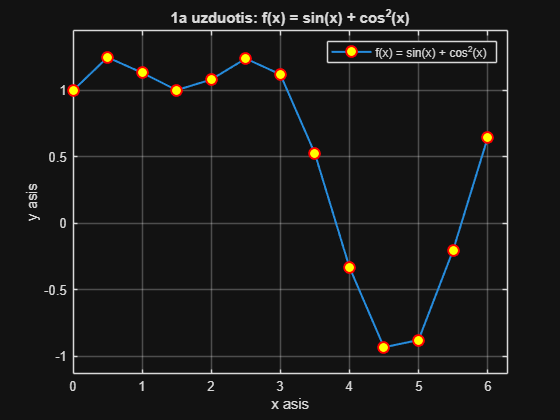

figure(1);
x = 0 : 0.5 : 2*pi;
f = sin(x) + cos(x).^2;
plot(x, f, '-o', ...
    'MarkerEdgeColor', 'r', ...
    'MarkerFaceColor', 'y', ...
    'MarkerSize', 8, ...
    'LineWidth', 1.5);

grid on;
title('1a uzduotis: f(x) = sin(x) + cos^2(x)');
xlabel('x asis');
ylabel('y asis');
axis([0 2*pi min(f)-0.2 max(f)+0.2]);
legend('f(x) = sin(x) + cos^2(x)', 'Location', 'northeast');

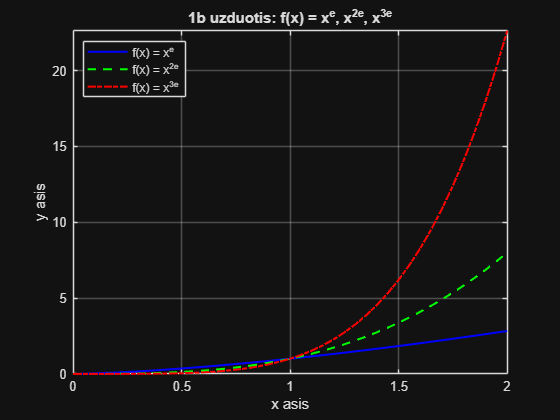


figure(2);
e = 1.5;
x = 0 : 0.05 : 2;
f1 = x.^e;
f2 = x.^(2*e);
f3 = x.^(3*e);
plot(x, f1, 'b-', 'LineWidth', 1.5); hold on;
plot(x, f2, 'g--', 'LineWidth', 1.5);
plot(x, f3, 'r-.', 'LineWidth', 1.5);
hold off;

grid on;
title('1b uzduotis: f(x) = x^e, x^{2e}, x^{3e}');
xlabel('x asis');
ylabel('y asis');
all_f = [f1, f2, f3];
axis([min(x) max(x) min(all_f) max(all_f)]);
legend('f(x) = x^e', 'f(x) = x^{2e}', 'f(x) = x^{3e}', 'Location', 'northwest');

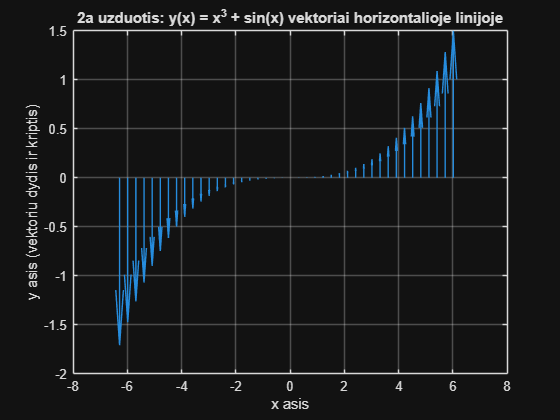

figure(3);
x = -2*pi : 0.3 : 2*pi;
y = x.^3 + sin(x);
u = zeros(size(x));
v = y;
quiver(x, zeros(size(x)), zeros(size(x)), y);

grid on;
title('2a uzduotis: y(x) = x^3 + sin(x) vektoriai horizontalioje linijoje');
xlabel('x asis');
ylabel('y asis (vektoriu dydis ir kriptis)');

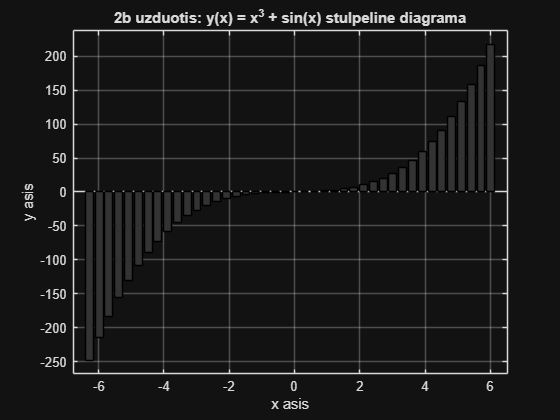


figure(4);
x = -2*pi : 0.3 : 2*pi;
y = x.^3 + sin(x);
bar(x, y, 'FaceColor', [0.2 0.2 0.2], 'EdgeColor', 'k');
grid on;
title('2b uzduotis: y(x) = x^3 + sin(x) stulpeline diagrama');
xlabel('x asis');
ylabel('y asis');
axis([min(x)-0.5 max(x)+0.5 min(y)-20 max(y)+20]);

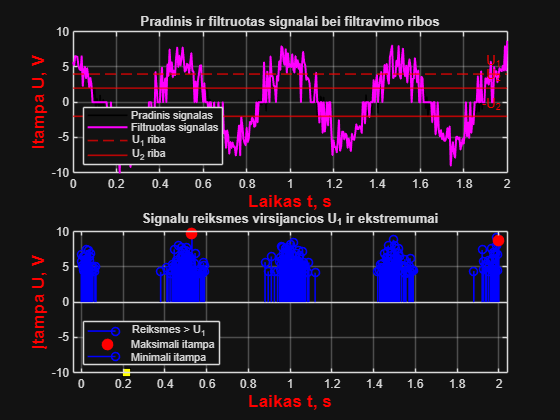

A = 6;
f = 2;
sigma = 1.5;
U1 = 4;
U2 = 2;

t = 0:0.005:2;

s_svarus = A * cos(2 * pi * f * t);
n = sigma * randn(size(t));
s = s_svarus + n;

s_filtruotas = s;
s_filtruotas(abs(s_filtruotas) < U2) = 0;

figure(1);
subplot(2, 1, 1);
plot(t, s, 'k-', 'LineWidth', 1.2); hold on;
plot(t, s_filtruotas, 'm-', 'LineWidth', 1.5);
yline(U1, '--r', 'U_1', 'LineWidth', 1.2);
yline(U2, '-r', 'U_2', 'LineWidth', 1.2);
yline(-U2, '-r', '-U_2', 'LineWidth', 1.2);
hold off;
grid on;
title('Pradinis ir filtruotas signalai bei filtravimo ribos');
xlabel('Laikas t, s', 'Color', 'r', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Itampa U, V', 'Color', 'r', 'FontSize', 13, 'FontWeight', 'bold');
legend('Pradinis signalas', 'Filtruotas signalas', 'U_1 riba', 'U_2 riba', 'Location', 'southwest');


subplot(2, 1, 2);
idx_virsija = s > U1;
t_virsija = t(idx_virsija);
s_virsija = s(idx_virsija);
stem(t_virsija, s_virsija, 'b', 'LineWidth', 1.2); hold on;
[max_val, max_idx] = max(s);
[min_val, min_idx] = min(s);
plot(t(max_idx), max_val, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(t(min_idx), min_val, 'sy', 'MarkerSize', 8, 'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k');
hold off;
grid on;
title('Signalu reiksmes virsijancios U_1 ir ekstremumai');
xlabel('Laikas t, s', 'Color', 'r', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Įtampa U, V', 'Color', 'r', 'FontSize', 13, 'FontWeight', 'bold');
legend('Reiksmes > U_1', 'Maksimali itampa', 'Minimali itampa', 'Location', 'southwest');